Statistics 

load('Schedule_data_index.mat');
%for j = 1:5
    for  i = 1:20
        data_s_t1 = Schedule_data_index(i,1);
        data_s_a1 = data_s_t1.Data;
        data_s1(i,:) = sum(data_s_a1);
    end
    for  i = 1:20
        data_s_t2 = Schedule_data_index(i,2);
        data_s_a2 = data_s_t2.Data;
        data_s2(i,:) = sum(data_s_a2);
    end
    for  i = 1:20
        data_s_t3 = Schedule_data_index(i,3);
        data_s_a3 = data_s_t3.Data;
        data_s3(i,:) = sum(data_s_a3);
    end
    for  i = 1:20
        data_s_t4 = Schedule_data_index(i,4);
        data_s_a4 = data_s_t4.Data;
        data_s4(i,:) = sum(data_s_a4);
    end
    for  i = 1:20
        data_s_t5 = Schedule_data_index(i,5);
        data_s_a5 = data_s_t5.Data;
        data_s5(i,:) = sum(data_s_a5);
    end
    
%end
data_s_n1 = data_s1(:,[1:5])./data_s1(:,6);
data_s_n2 = data_s2(:,[1:5])./data_s2(:,6);
data_s_n3 = data_s3(:,[1:5])./data_s3(:,6);
data_s_n4 = data_s4(:,[1:5])./data_s4(:,6);
data_s_n5 = data_s5(:,[1:5])./data_s5(:,6);
%%

Non randomized plot

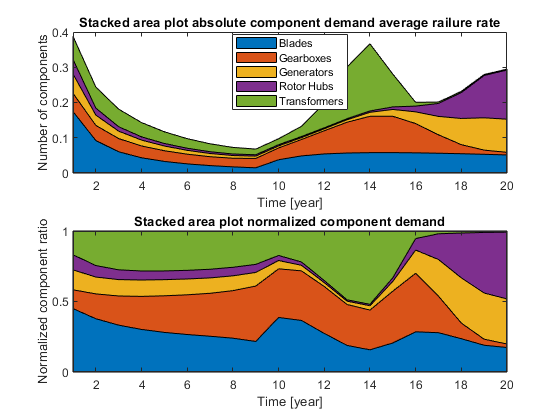

load('failure_rate.mat','failure_rate');
failure_rate_sum = sum(failure_rate);
failure_rate_norm = failure_rate./failure_rate_sum;
failure_rate = transpose(failure_rate);
failure_rate_norm = transpose(failure_rate_norm);
figure()
g1 = subplot(2,1,1);
area(failure_rate)
title(g1,'Stacked area plot absolute component demand average railure rate')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(failure_rate_norm);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);

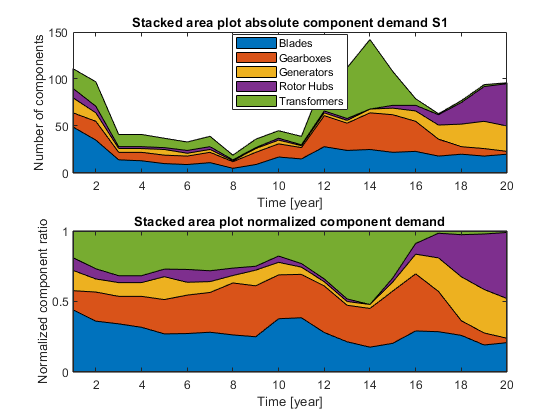

figure()
g1 = subplot(2,1,1);
area(data_s1(:,[1:5]))
title(g1,'Stacked area plot absolute component demand S1')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(data_s_n1);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);

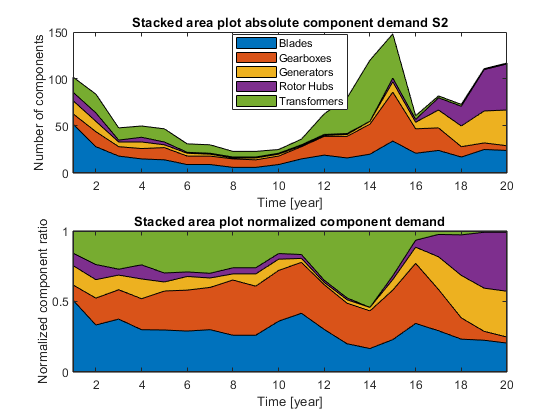

%
figure()
g1 = subplot(2,1,1);
area(data_s2(:,[1:5]))
title(g1,'Stacked area plot absolute component demand S2')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(data_s_n2);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);

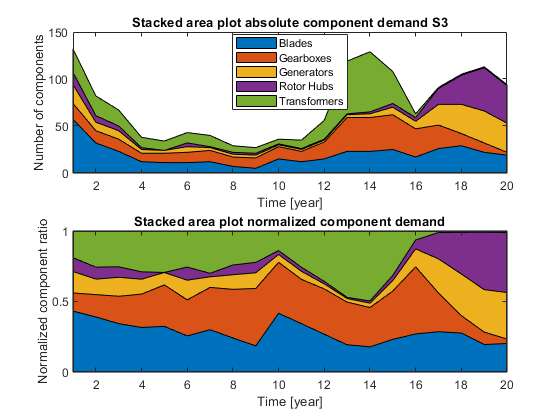

%
figure()
g1 = subplot(2,1,1);
area(data_s3(:,[1:5]))
title(g1,'Stacked area plot absolute component demand S3')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(data_s_n3);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);

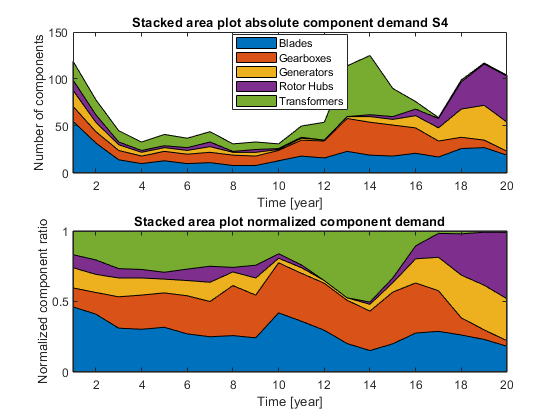

%
figure()
g1 = subplot(2,1,1);
area(data_s4(:,[1:5]))
title(g1,'Stacked area plot absolute component demand S4')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(data_s_n4);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);

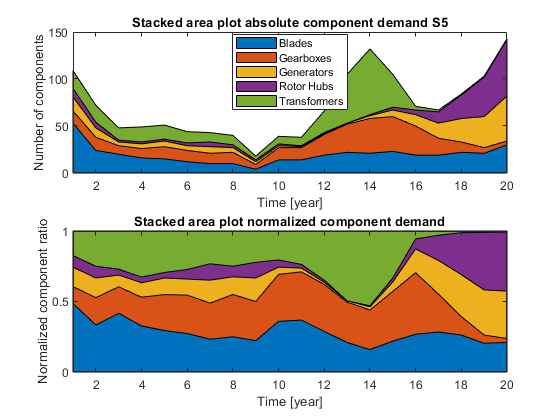

%
figure()
g1 = subplot(2,1,1);
area(data_s5(:,[1:5]))
title(g1,'Stacked area plot absolute component demand S5')
xlabel('Time [year]')
ylabel('Number of components')
legend({'Blades','Gearboxes','Generators','Rotor Hubs','Transformers'},'Location','best')
xlim([1 20]);
%
g2 = subplot(2,1,2);
area(data_s_n5);
title(g2,'Stacked area plot normalized component demand')
xlabel('Time [year]')
ylabel('Normalized component ratio')
xlim([1 20]);